## OPSR - referát

### Inicializace

clc
clearvars

### Zadané

g = 9.81373 %m/s2 Tíhové zrychlení pro Prahu

g = 9.8137

ro = 997 %kg/m³

ro = 997

mi_1 = 0.6 %Výtokový koeficient -> měl by být mezi 0.6 - 0.62

mi_1 = 0.6000

mi_2 = mi_1 %Výtokový koeficient

mi_2 = 0.6000

d_1 = 0.05 %m Průměr první nádrže

d_1 = 0.0500

d_2 = d_1 %m Průměr druhé nádrže

d_2 = 0.0500

d_c1 = 0.004 %m Průměr clonky první nádrže

d_c1 = 0.0040

d_c2 = d_c1 %m Průměr clonky druhé nádrže

d_c2 = 0.0040

d_sr = 1 %m Průměr kruhu, na který dopadá déšť

d_sr = 1

h1_max = 0.3 %m Maximální výška první nádrže

h1_max = 0.3000

h2_max = 0.3 %m Maximální výška druhé nádrže

h2_max = 0.3000

U_max = 10 %V Maximální napětí čerpadla

U_max = 10

### Dopočtené

S_1 = (pi*d_1*d_1)/4 %m2 Plocha první nádrže

S_1 = 0.0020

S_2 = (pi*d_2*d_2)/4 %m2 Plocha druhé nádrže

S_2 = 0.0020

S_c1 = (pi*d_c1*d_c1)/4 %m2 Plocha clonky první nádrže

S_c1 = 1.2566e-05

S_c2 = (pi*d_c2*d_c2)/4 %m2 Plocha clonky druhé nádrže

S_c2 = 1.2566e-05

S_sr = (pi*d_sr*d_sr)/4 %m2 Plocha clonky druhé nádrže

S_sr = 0.7854

### Definované vztahy

Q_0_lm = @(u) 0.0031*u^3 - 0.0532*u^2 + 0.4043*u - 0.2445; %l/min Výpočet průtoku z napětí 
Q_0 = @(u) Q_0_lm(u)/60000; %m3/s Výpočet průtoku z napětí

Q_sr = @(R) (S_sr*R)/3600000; %m3/s Výpočet průtoku ze srážek
Q_sr_lm = @(R) Q_sr*60000; %l/min Výpočet průtoku ze srážek

## Linearizovaný model

%Definice symbolických proměnných
g_s = sym('g');
mi_1_s = sym('mu_1');
mi_2_s = sym('mu_2');
S1_s = sym('S_1');
S2_s = sym('S_2');
Sc1_s = sym('S_c1');
Sc2_s = sym('S_c2');
Ssr_s = sym('S_sr');

h1_s = sym('h_1');
h2_s = sym('h_2');
U_s = sym('U');
R_s = sym('R');

%Vstupy
u = [U_s;R_s];
%Stavové vektory
x = [h1_s;h2_s];
y = [h1_s;h2_s];

#### Pracovní bod

h2 = (Q_0(4.5)/(mi_2*S_c2*sqrt(2*g)))^2 %Výpočet h v ustáleném stavu

h2 = 0.1515


%Pravobní bod
h1_p = 0.15; %m
h2_p = 0.15; %m
h_p = [h1_p;h2_p];
U_p = 4.5; %V
R_p = 0; %mm/hod
u_p = [U_p; R_p];

#### Rovnice popisující nelineární systém

%Nelineární systém
dh1 = (Q_0(U_s) ...
      +Q_sr(R_s) ...
      - (mi_1_s*Sc1_s*sqrt(2*g_s*h1_s)))/S1_s

$$dh1 = \frac{\frac{4043\,U}{600000000}+\frac{\pi \,R}{14400000}-\frac{133\,U^{2}}{150000000}+\frac{31\,U^{3}}{600000000}-\sqrt{2}\,S_{\mathrm{c1}}\,\mu_{1}\,\sqrt{g\,h_{1}}-\frac{163}{40000000}}{S_{1}}$$

%vpa(dh1,4)
dh2 = ((mi_1_s*Sc1_s*sqrt(2*g_s*h1_s)) ...
      -(mi_2_s*Sc2_s*sqrt(2*g_s*h2_s)))/S2_s

$$dh2 = \frac{\sqrt{2}\,S_{\mathrm{c1}}\,\mu_{1}\,\sqrt{g\,h_{1}}-\sqrt{2}\,S_{\mathrm{c2}}\,\mu_{2}\,\sqrt{g\,h_{2}}}{S_{2}}$$


dX = [dh1; dh2]

$$dX = \left(\begin{array}{c} \frac{\frac{4043\,U}{600000000}+\frac{\pi \,R}{14400000}-\frac{133\,U^{2}}{150000000}+\frac{31\,U^{3}}{600000000}-\sqrt{2}\,S_{\mathrm{c1}}\,\mu_{1}\,\sqrt{g\,h_{1}}-\frac{163}{40000000}}{S_{1}}\\ \frac{\sqrt{2}\,S_{\mathrm{c1}}\,\mu_{1}\,\sqrt{g\,h_{1}}-\sqrt{2}\,S_{\mathrm{c2}}\,\mu_{2}\,\sqrt{g\,h_{2}}}{S_{2}} \end{array}\right)$$


y1 = h1_s;
y2 = h2_s;
Y = [y1;y2]

$$Y = \left(\begin{array}{c} h_{1}\\ h_{2} \end{array}\right)$$

#### Výpočet Jacobiho matice

%Výpočet jakobiánu
A.symbolic = jacobian(dX, x);
B.symbolic = jacobian(dX, u);
C.symbolic = jacobian(Y,x);
D.symbolic = jacobian(Y,u);

A.symbolic

$$ans = \left(\begin{array}{cc} -\frac{\sqrt{2}\,S_{\mathrm{c1}}\,g\,\mu_{1}}{2\,S_{1}\,\sqrt{g\,h_{1}}} & 0\\ \frac{\sqrt{2}\,S_{\mathrm{c1}}\,g\,\mu_{1}}{2\,S_{2}\,\sqrt{g\,h_{1}}} & -\frac{\sqrt{2}\,S_{\mathrm{c2}}\,g\,\mu_{2}}{2\,S_{2}\,\sqrt{g\,h_{2}}} \end{array}\right)$$

vpa(B.symbolic,4)

$$ans = \left(\begin{array}{cc} \frac{1.55e-7\,U^{2}-1.773e-6\,U+6.738e-6}{S_{1}} & \frac{2.182e-7}{S_{1}}\\ 0 & 0 \end{array}\right)$$

C.symbolic

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

D.symbolic

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

#### Výpočet matic A, B, C, D linearizovaného systému

%Dosazení do proměnných
A.algebraic = simplify(subs(A.symbolic, ...
    {Sc1_s    g_s     mi_1_s    S1_s    h1_s      Sc2_s     mi_2_s   S2_s      h2_s}, ...
   [sym(S_c1) sym(g) sym(mi_1) sym(S_1) sym(h1_p) sym(S_c2) sym(mi_2) sym(S_2) sym(h2_p)]));

B.algebraic = simplify(subs(B.symbolic, ...
    {S1_s            U_s            Ssr_s}, ...
   [sym(S_1)         sym(U_p)       sym(S_sr)]));

C.algebraic = simplify(C.symbolic);
D.algebraic = simplify(D.symbolic);

A.algebraic;
B.algebraic;
C.algebraic;
D.algebraic;

%Výpočet numerických hodnot
A.eval = eval(A.algebraic);
B.eval = eval(B.algebraic);
C.eval = eval(C.algebraic);
D.eval = eval(D.algebraic);

vpa(sym(A.eval),3)

$$ans = \left(\begin{array}{cc} -0.022 & 0\\ 0.022 & -0.022 \end{array}\right)$$

vpa(sym(B.eval),3)

$$ans = \left(\begin{array}{cc} 9.66e-4 & 1.11e-4\\ 0 & 0 \end{array}\right)$$

vpa(sym(C.eval),3)

$$ans = \left(\begin{array}{cc} 1.0 & 0\\ 0 & 1.0 \end{array}\right)$$

vpa(sym(D.eval),3)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

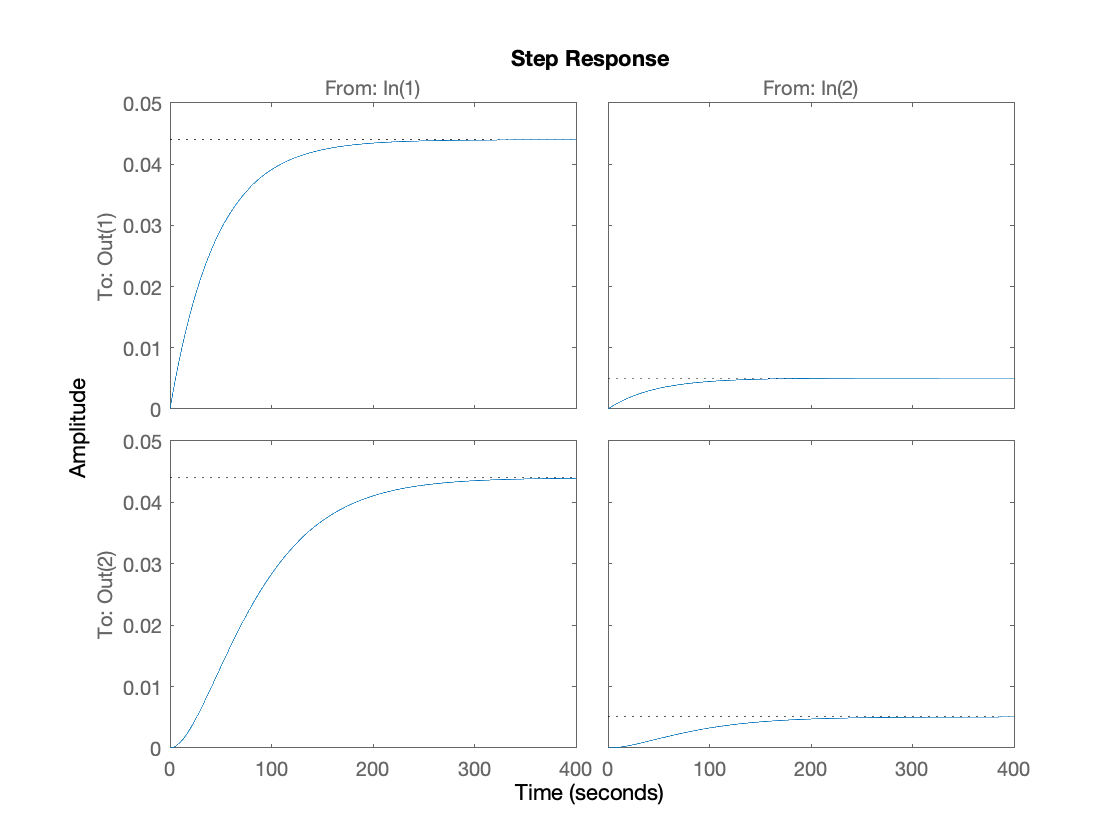


%Vytvoření lineárního systému
sys_lin = ss(A.eval, B.eval, C.eval, D.eval);
step(sys_lin);

## Diskrétní model linearizovaného systému

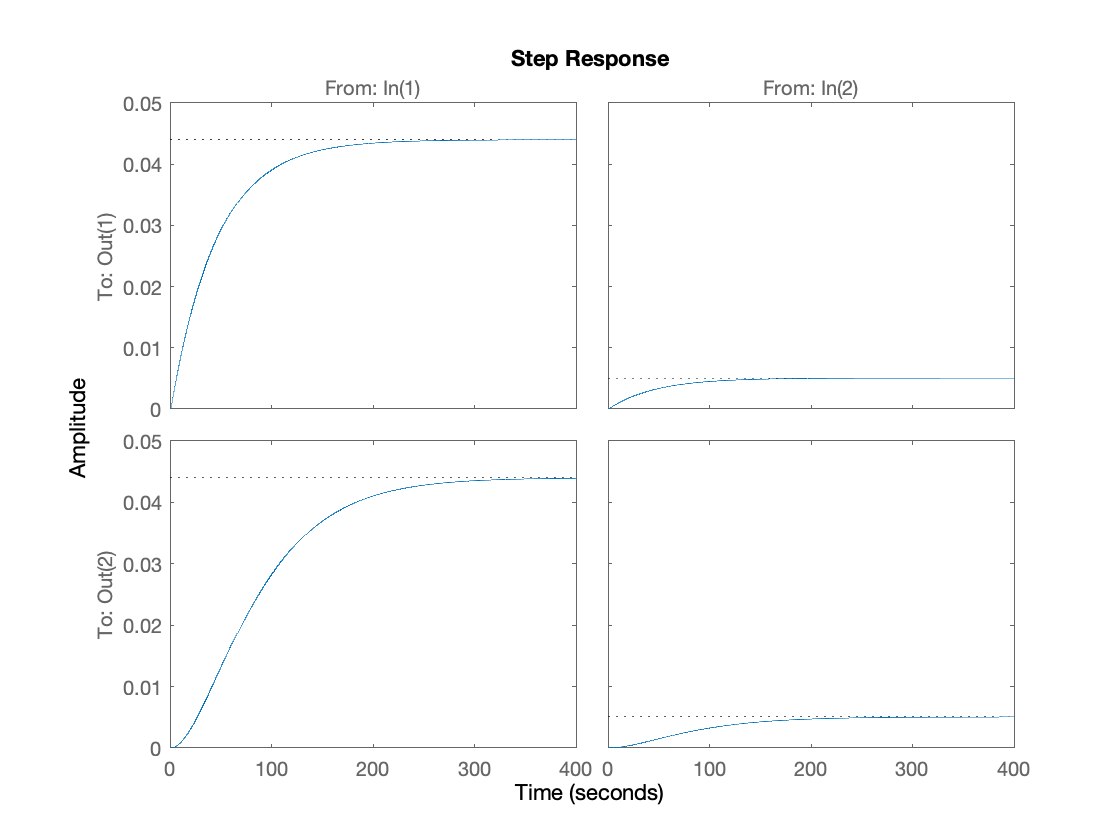

Ts = 1;
sys_lin_d = c2d(sys_lin, Ts);
step(sys_lin_d)


A_d = sys_lin_d.A;
B_d = sys_lin_d.B;
C_d = sys_lin_d.C;
D_d = sys_lin_d.D;

### Simulace (pro odhad kroku)

x0_d = [0.17;0.17]; %Ustálené hodnoty pro 5V
T_sim = 300;
N = T_sim/Ts;
Uk = 6*ones(N,1)'; %Skok na 6V
Rk = 0*ones(N,1)'; %Neprší
tk = Ts*[0:1:N]

tk =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


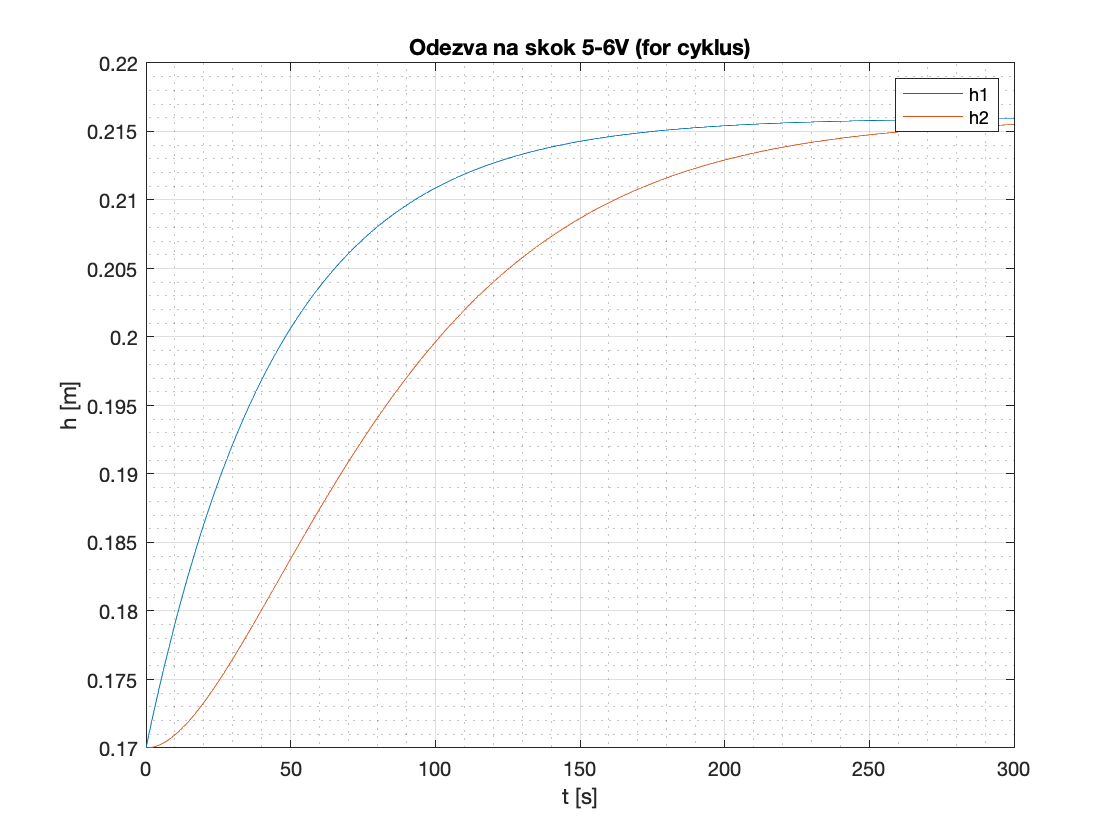

uk = [Uk;Rk];
x = x0_d;
yk = C_d*x;

for k=1:N
    %Přesunutí do pracovního bodu
    u = uk(:,k)-u_p;
    x = x-h_p;
    %Výpočet nových stavových proměnných
    x = A_d*x +B_d*u;
    %Přesunutí z pracovního bodu
    x = x+h_p;
    y = C_d*x;
    yk = [yk y];
end

figure
plot(tk,yk(1,:))
hold on
plot(tk, yk(2,:))
title('Odezva na skok 5-6V (for cyklus)')
xlabel('t [s]')
ylabel('h [m]')
grid on
grid minor
legend('h1', 'h2');

### Simulace všech kroků najednou

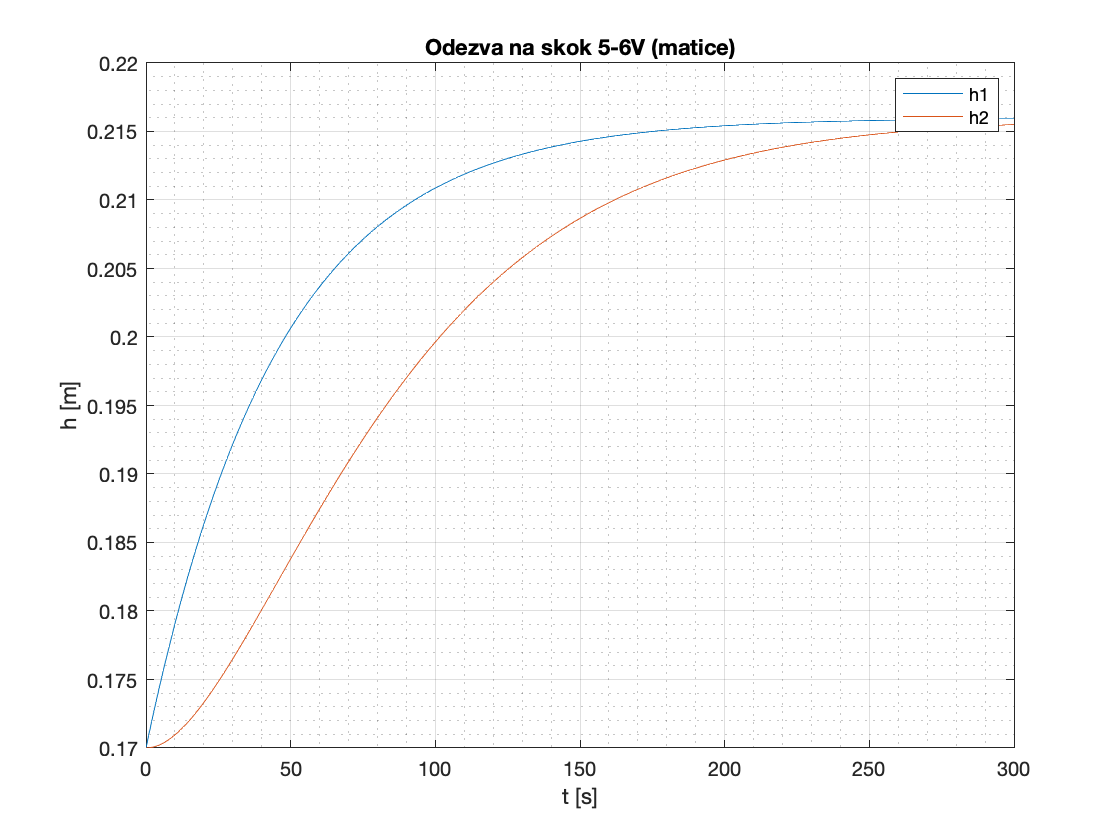

[P,S1,S2] = predssd(A_d, B_d(:,1),B_d(:,2), C_d, N);
%Přesunutí do pracovního bodu
Uk_p = Uk' - U_p*ones(N,1);
Rk_p = Rk' - R_p*ones(N,1);
X0_p = x0_d - [h1_p;h2_p];


%Simulace
[Y_c1, Y_c2] = dv(P*X0_p + S1*Uk_p + S2*Rk_p);

%Přesunutí z pracobního bodu
Y_c1 = Y_c1 + h1_p*ones(N,1);
Y_c2 = Y_c2 + h2_p*ones(N,1);

figure
plot(tk,[x0_d(1);Y_c1]')
hold on
plot(tk, [x0_d(2);Y_c2]')
title('Odezva na skok 5-6V (matice)')
xlabel('t [s]')
ylabel('h [m]')
grid on
grid minor
legend('h1', 'h2');

## Optimální zásah

X0_optz = [0.17;0.17]; %Ustálené hodnoty pro 5V
U0_optz = 5;
T_optz = 300;
N_optz = T_optz/Ts;
Rs_optz = [0*ones(N_optz/2,1);5*ones(N_optz/2,1)]; %Neprší
w_optz = 0.215*ones(N_optz,1); %Odpovídá ustálené hodnotě pro 6V
t_optz = (Ts*[0:1:N_optz])';
U_optz_max = 20*ones(N_optz,1);
U_optz_min = 2*ones(N_optz,1);

%Převod modelu
[P_optz,S1_optz,S2_optz] = predssd(A_d, B_d(:,1),B_d(:,2), [0,1], N_optz);
[P_optz_sim,S1_optz_sim,S2_optz_sim] = predssd(A_d, B_d(:,1),B_d(:,2), C_d, N_optz);


%Parametry kritéria J = e'*T*e + R*U + dU'*S*dU
Q_optz = 100*eye(N_optz); %odchylka
R_optz = 100*eye(1,N_optz); %spotřeba vody
S_optz = 1*eye(N_optz);%rychlost změny čerpání vody

%Přesunutí do pracovního bodu
Rs_optz_p = Rs_optz - R_p*ones(N_optz,1);
w_optz_p = w_optz - h2_p*ones(N_optz,1);
X0_optz_p = X0_optz - h_p;
U_optz_min_p = U_optz_min - U_p*ones(N_optz,1);
U_optz_max_p = U_optz_max - U_p*ones(N_optz,1);
U0_optz_p = U0_optz - U_p;

%Chci minimální odchylku hladiny a regulační odchylku
[H_optz, f_optz] = calculateHf(Q_optz, R_optz,S_optz,P_optz,S1_optz,S2_optz,w_optz_p,X0_optz_p,Rs_optz_p,U0_optz_p);

JN = 962.2932

JN = 962.2932

JN = 962.2932

JN = 962.2932

JN = 962.2932

JN = 962.2932

%U_optz = -H_optz\f_optz';
[U_optz,f_val] = quadprog(H_optz,f_optz,[],[],[],[],U_optz_min_p, U_optz_max_p);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


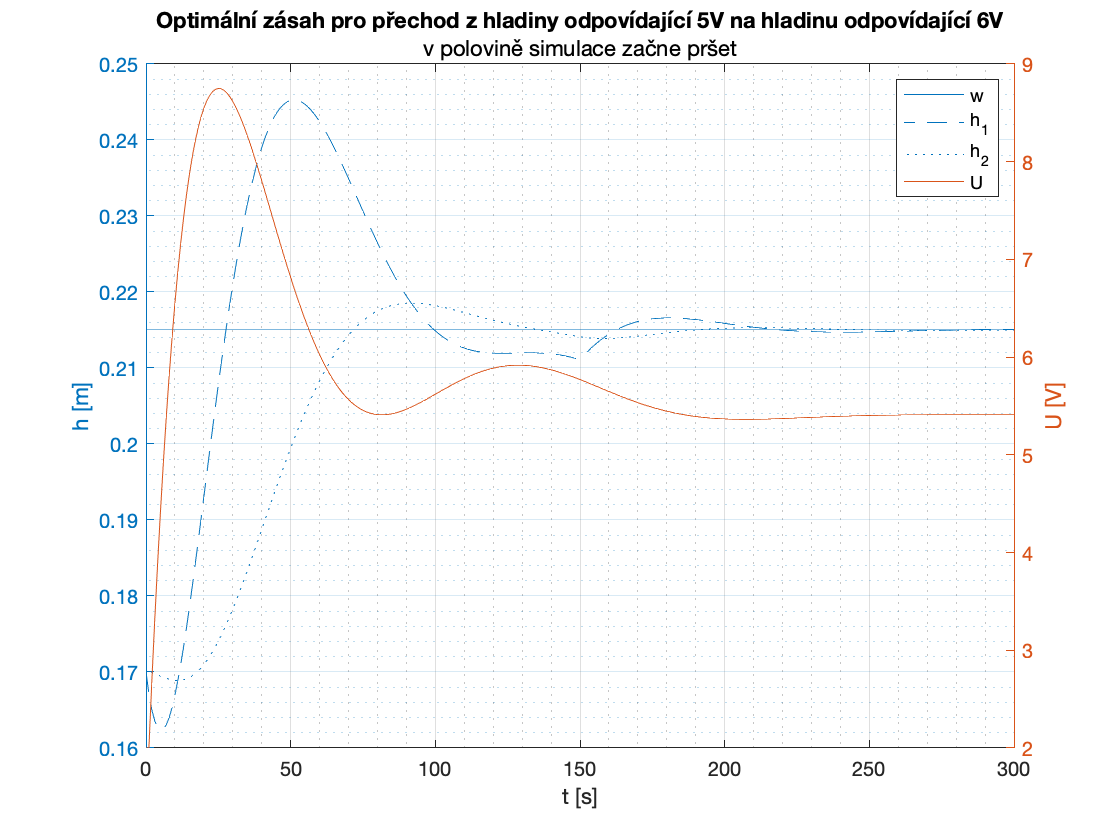

%U_optz = (6-U_p)*ones(N_optz,1);


%Simulace
[h1_optz_p, h2_optz_p] = dv(P_optz_sim*X0_optz_p + S1_optz_sim*U_optz + S2_optz_sim*Rs_optz_p);

%Přesunutí z pracobního bodu
h1_optz = h1_optz_p + h1_p*ones(N_optz,1);
h2_optz = h2_optz_p + h2_p*ones(N_optz,1);
U_optz = U_optz + U_p*ones(N_optz,1);
h1_optz = [X0_optz(1);h1_optz]; %přidá počáteční hodnotu
h2_optz = [X0_optz(2);h2_optz]; %přidá počáteční hodnotu
w_optz = [0.215;w_optz]; %přidá počáteční hodnotu
U_optz = [U_optz(1); U_optz]; %přidá počáteční hodnotu

figure
yyaxis left
title('Optimální zásah pro přechod z hladiny odpovídající 5V na hladinu odpovídající 6V','v polovině simulace začne pršet')
plot(t_optz,w_optz)
hold on
plot(t_optz,h1_optz)
hold on
plot(t_optz,h2_optz)
xlabel('t [s]')
ylabel('h [m]')
hold on
yyaxis right
ylabel('U [V]')
plot(t_optz,U_optz)
legend('w','h_1','h_2','U')
grid on
grid minor

## MPC

T_mpc = 1000; %s Doba simulace MPC
t = (0:Ts:(T_mpc-Ts))'; %Reálný čas
N_mpc = T_mpc/Ts %Počet kroků simulace

N_mpc = 1000

[P_mpc,S1_mpc,S2_mpc] = predssd(A_d, B_d(:,1),B_d(:,2), [1,0], N_mpc);

### Definice srážek

R_mpc_mod = [0*ones(N_mpc/4,1); %čtvrtinu času neprší
             5*ones(N_mpc/4,1); %čtvrtinu času je běžný déšť
             10*ones(N_mpc/4,1); %čtvrtinu času je průtrž mračen
             0*ones(N_mpc/4,1)] %čtvrtinu času neprší

R_mpc_mod =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


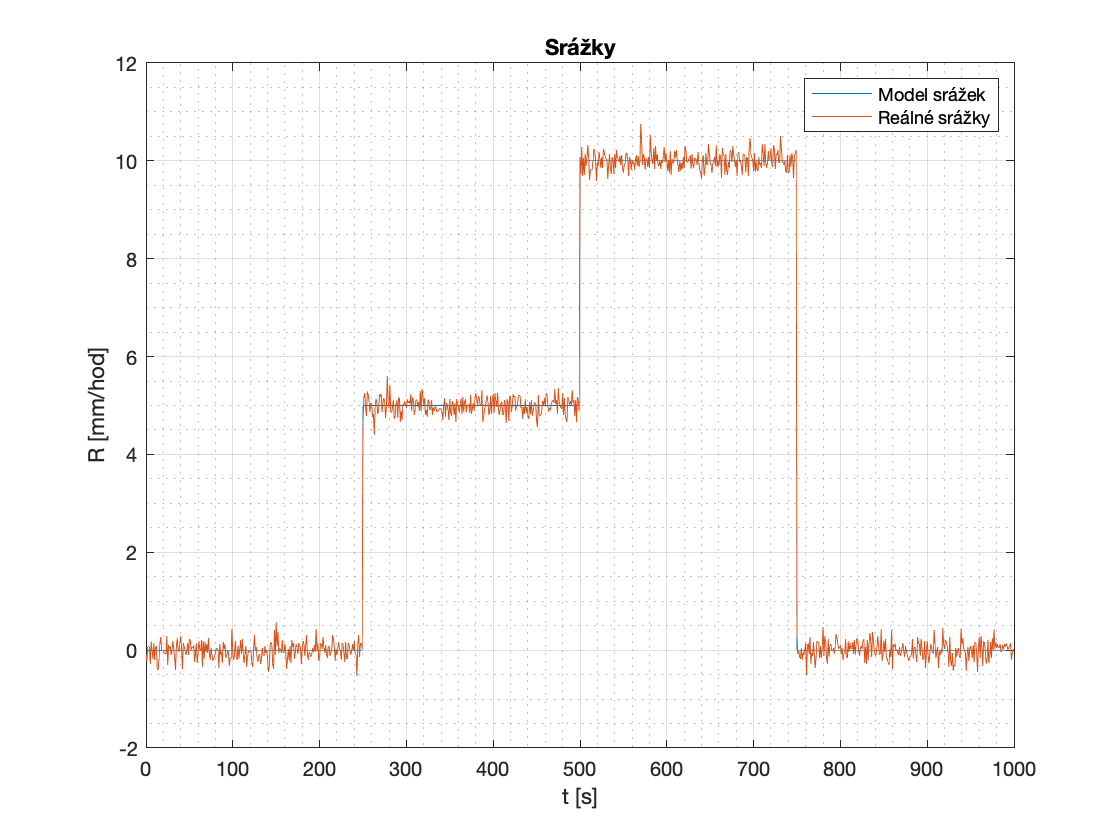

R_mpc_real = awgn(R_mpc_mod,30,'measured');

figure
plot(t,[R_mpc_mod R_mpc_real])
title('Srážky')
xlabel('t [s]')
ylabel('R [mm/hod]')
grid on
grid minor
legend('Model srážek','Reálné srážky')

### Definice výšky $h_2$

w_mpc = [h_p(2)*ones(N_mpc/2,1); %polovičku času je požadována výška 0.15 (pracovní bod linearizace)
         (h_p(2)+0.02)*ones(N_mpc/2,1)] %v druhé polovině času dojde k požadavku na zvýšení

w_mpc =     0.1500
    0.1500
    0.1500
    0.1500
    0.1500
    0.1500
    0.1500
    0.1500
    0.1500
    0.1500


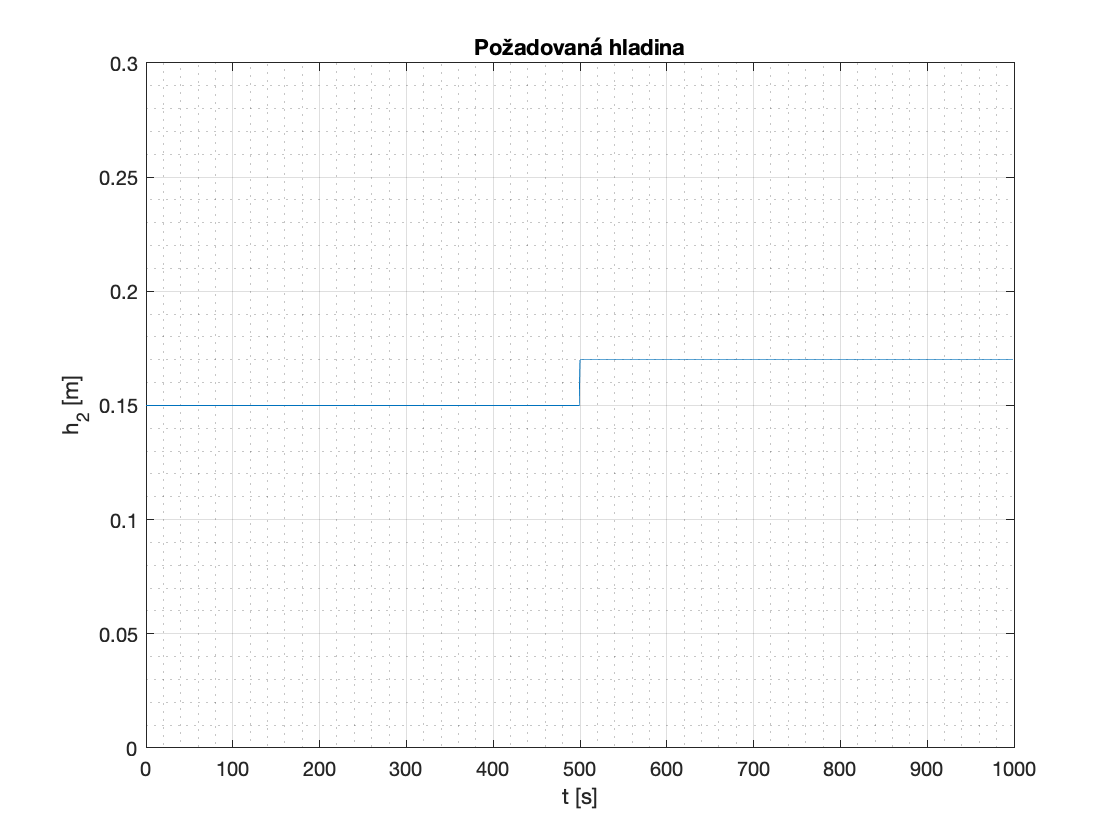


figure
plot(t,w_mpc)
title('Požadovaná hladina')
xlabel('t [s]')
ylabel('h_2 [m]')
ylim([0,h2_max])
grid on
grid minor